# Svolgimento di un esercizio in ambiente MATLAB

#### dal file eser_svolti.pdf, esercizio 1

Con riferimento al sistema di figura, calcolare:

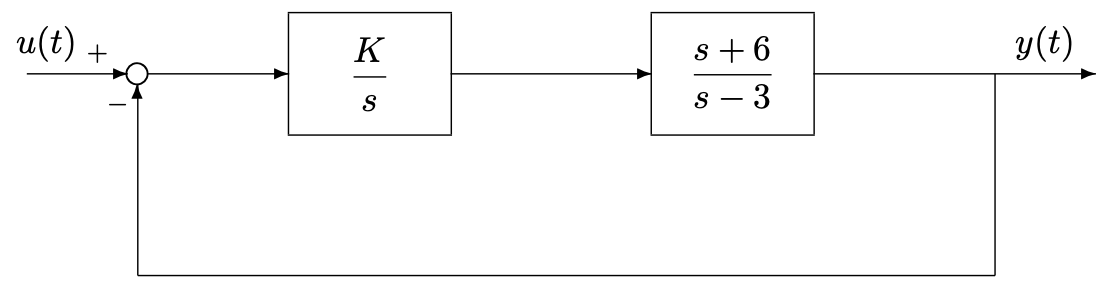

(1) La funzione di trasferimento a ciclo chiuso tra $u(t)$e $y(t)$;

(2) I valori di K per i quali il sistema a ciclo chiuso risulta asintoticamente stabile;

(3) Il valore di K per il quale il sistema a ciclo chiuso presenta poli con coefficiente di smorzamento $\zeta = \frac{1}{4}$. Per tale valore di K:

    (a) si traccino i diagrammi di Bode relativi al sistema a ciclo chiuso

    (b) si calcoli la risposta $y(t)$ in presenza di un ingresso a gradino $u(t) = \delta_{-1}(t)$

    (c) si calcoli la risposta $y(t)$ in presenza di un ingresso $u(t) = \sin(6t) + \sin(60t)$

#### (1)

Definiamo la variabile s, il parametro K e le due funzioni di trasferimento:

syms s K;
G1 = K/s

$$G1 = \frac{K}{s}$$

G2 = (s+6)/(s-3)

$$G2 = \frac{s+6}{s-3}$$

Essendo il sistema totale una retroazione della serie di due sistemi, la funzione di trasferimento sarà


$$G(s) = \frac{G_1(s)G_2(s)}{1+G_1(s)G_2(s)}$$


G = (G1 .* G2)/(1 + (G1 .* G2));
G = simplifyFraction(G);
G = collect(G,s)                        % raccolgo per evidenziare i coefficienti di s

$$G = \frac{K\,s+6\,K}{s^{2}+\left(K-3\right)\,s+6\,K}$$

#### (2)

Affinchè il sistema a ciclo chiuso sia asintoticamente stabile, è necessario che le radici del denominatore della sua funzione di trasferimento abbiano tutte parte reale negativa: per effettuare questo controllo, possiamo applicare il criterio di Cartesio.

Il coefficiente del termine di secondo grado $s^2$ è pari a $+1$. Servono quindi due permanenze:


$$\begin{cases} K-3 > 0 \\ 6K>0\end{cases}
\qquad\iff\qquad
K>3$$


#### (3)

Osservando l'espressione della funzione di trasferimento

G

$$G = \frac{K\,s+6\,K}{s^{2}+\left(K-3\right)\,s+6\,K}$$

Osserviamo che la pulsazione naturale vale $\omega_n = \sqrt{6K}$ e il coefficiente di smorzamento $\zeta = \frac{K-3}{2\sqrt{6K}}$.

Calcoliamo ora il valore di zita affinchè $\zeta = \frac{1}{4}$:

zita = (K-3)/(2*sqrt(6*K));
k = simplify(solve(zita==1/4,K))

$$k = 6$$

Andiamo a sostituire il valore appena trovato nell'espressione della funzione di trasferimento:

G = subs(G,K,k)

$$G = \frac{6\,s+36}{s^{2}+3\,s+36}$$

Studiamo questa funzione di trasferimento:

data l'assenza di termini monomi, possiamo calcolare il coefficiente $k'$ semplicemente valutando $\left.G(s)\right|_{s=0}$:

k_primo = subs(G,s,0)

$$k\_primo = 1$$

Consideriamo il valore in decibel:

k_primo_db = mag2db(k_primo)

$$k\_primo\_db = 0$$

Ora valutiamo il punto di rottura dovuto al termine monomio al numeratore:

[num,~] = numden(G)

$$num = 6\,s+36$$

da cui $\left|\frac{1}{\tau_1}\right| = 6$;

la pulsazione di risonanza relativa alla coppia di poli complessi era stata calcolata precedentemente: $\omega_n = \sqrt{6\cdot6} = 6$;

ricordiamo infine il valore del coefficiente di smorzamento $\zeta = \frac{1}{4}$ (un valore "piccolo")

**(3a)**

Disegnamo il diagramma di Bode asintotico e reale della funzione di trasferimento (attenzione: è richiesto il file *asbode2.m*)

num = sym2poly(num);        % estraggo il vettore dei coefficienti del numeratore
[~,den] = numden(G);        % prelevo il denominatore dalla fdt
den = sym2poly(den);        % estraggo il vettore dei coefficienti del denominatore
figure(1),asbode2(num,den,[],[],[],0,0,0,3);


Guadagno:        K =   1.000,   K_db = 0 db,     phi = 0 deg
Zero reale:      z =  -6.000,   tau =   0.167,   1/|tau| =   6.000,   phi = da 0 a +90 deg
Poli complessi:  p,p' =  -1.500 +/- j  5.809,    omega_n =   6.000,   zeta =  0.25
                 beta =  1.8,                    omega_s =   3.374,   omega_d =  10.670,
                 phi = da 0 a -180 deg,          Delta M_db = +6 db


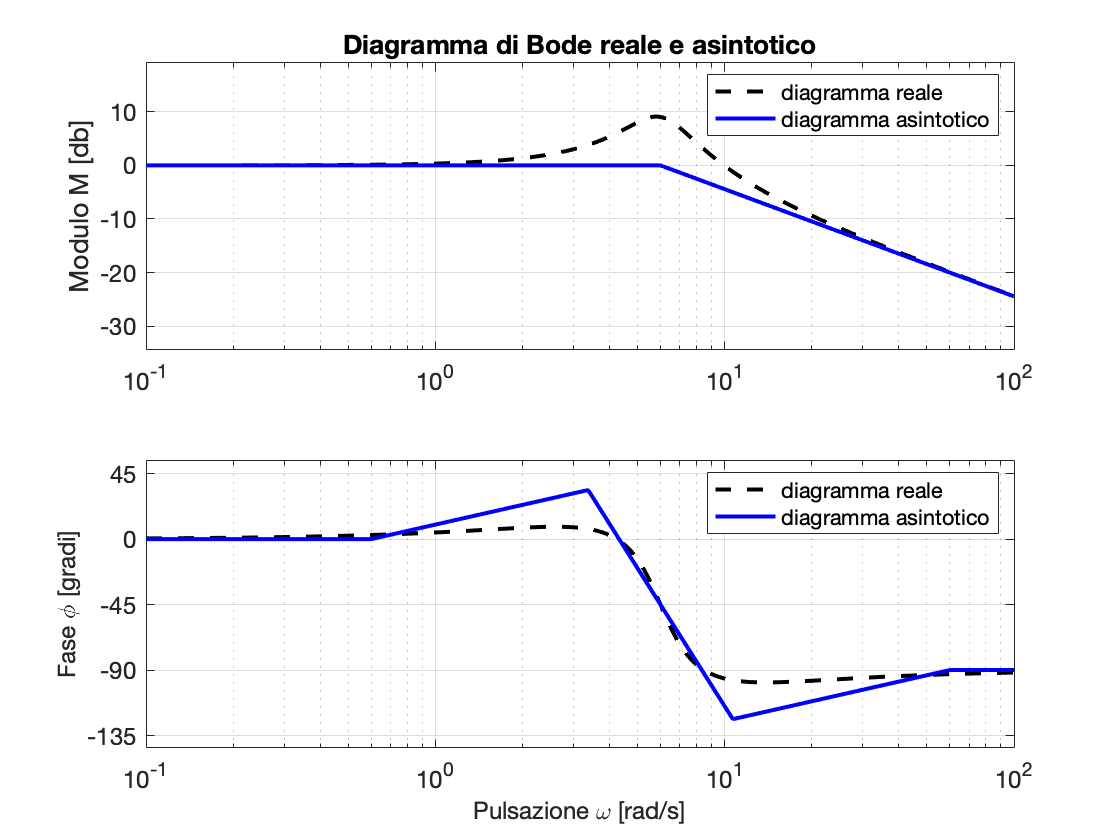

% aggiungo la legenda
subplot(2,1,1)
legend({'diagramma reale','diagramma asintotico'})
subplot(2,1,2)
legend({'diagramma reale','diagramma asintotico'})

Osserviamo i diagrammi asintotici.

**Modulo:**

Il diagramma parte con pendenza nulla (data l'assenza di termini monomio), ad altezza 0dB (valore di `k_primo_db`). Nel punto $\omega = 6$ il diagramma subisce una variazione di pendenza pari a $+20dB/dec -40dB/dec = -20dB/dec$. La correzione in $\omega = 6$ è pari a $+3dB$ per via dello zero e $\frac{1}{2\zeta} \approx +6dB$, per un totale di $+9dB$.

**Fase:**

Il diagramma parte a $0°$. In $\omega = 0.6$ la pendenza aumenta di $+45°/dec$. Nelle vicinanze di $\omega = 6$ la fase diminuisce bruscamente di $-180°$. Infine in $\omega = 60$ la pendenza diminuisce di $-45°/dec$, riportandosi a $0°/dec$ e assumendo un valore finale di $-90°$.

**(3b)**

Definiamo una variabile temporale:

syms t;

L'ingresso sarà il gradino unitario:

u = heaviside(t);

Per calcolare l'uscita possiamo usare la trasformata di Laplace: infatti, $Y(s) = G(s)U(s)$

U = laplace(u,s)        % L-trasformata del gradino unitario

$$U = \frac{1}{s}$$

Y = G*U

$$Y = \frac{6\,s+36}{s\,\left(s^{2}+3\,s+36\right)}$$

Antitrasformiamo $Y(s)$ per ottenere la risposta $y(t)$

y = ilaplace(Y,t)*heaviside(t)

$$y = -\mathrm{heaviside}\left(t\right)\,\left({\mathrm{e}}^{-\frac{3\,t}{2}}\,\left(\cos\left(\frac{3\,\sqrt{15}\,t}{2}\right)-\frac{\sqrt{15}\,\sin\left(\frac{3\,\sqrt{15}\,t}{2}\right)}{5}\right)-1\right)$$

(da notare che MATLAB utilizza la trasformata unilatera: ho dovuto manualmente aggiungere il gradino unitario a moltiplicare l'antitrasformata)

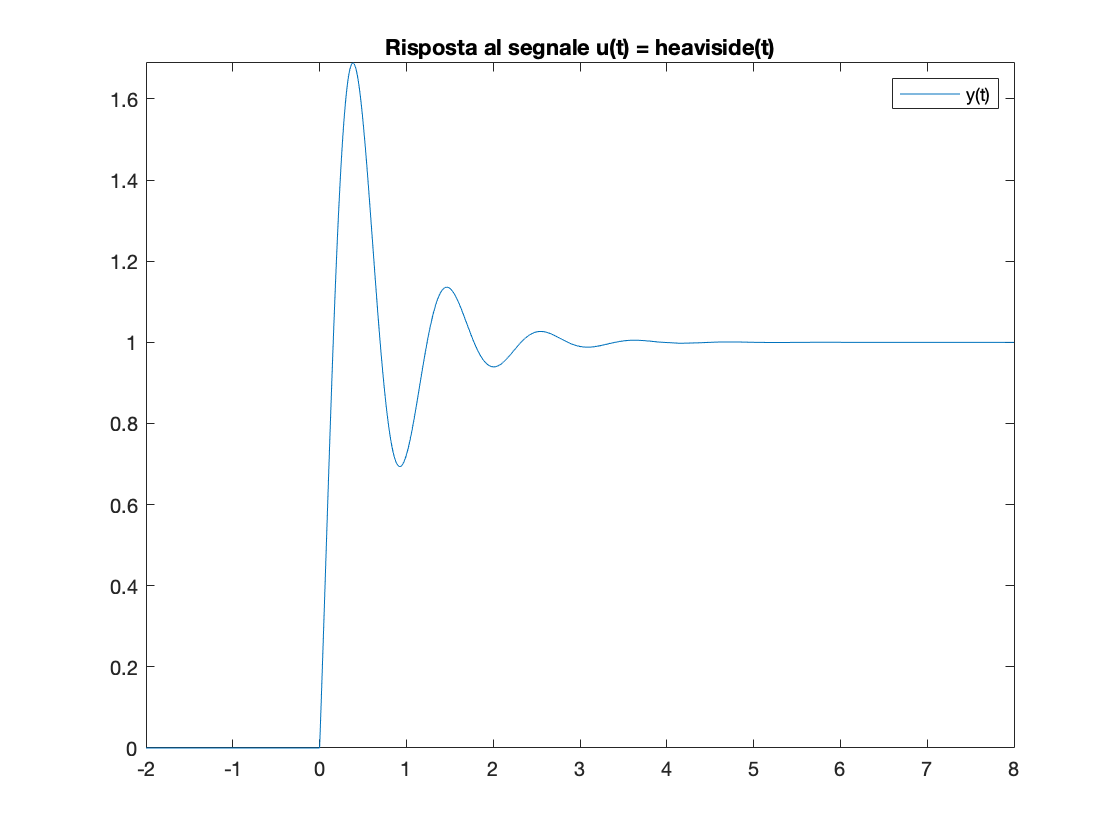

figure(2), fplot(y,[-2 8]), title('Risposta al segnale u(t) = heaviside(t)'), legend('y(t)')

**(3c)**

L'ingresso è costituito da due funzioni sinusoidali:


$$u(t) = \sin(6t) + \sin(60t)$$


Essendo il sistema asintoticamente stabile, ed essendo $u(t)$ applicato a partire da $-\infty$, la risposta corrisponde alla risposta a regime.

Dato che dal diagramma di Bode si nota che la frequenza $\omega = 60$ è molto attenuata rispetto alla frequenza $\omega = 6$, il segnale in uscita sarà con buona approssimazione la risposta a $u(t) = \sin(6t)$.

Calcoliamo modulo e fase della sinusoide in uscita:

M = abs(subs(G,s,1i*6))     % la nomenclatura 1i per l'unità immaginaria è consigliata da MATLAB

$$M = \sqrt{8}$$

phi = angle(subs(G,s,1i*6))

$$phi = -\frac{\pi }{4}$$

y = M * sin(6*t + phi)

$$y = \sqrt{8}\,\sin\left(6\,t-\frac{\pi }{4}\right)$$

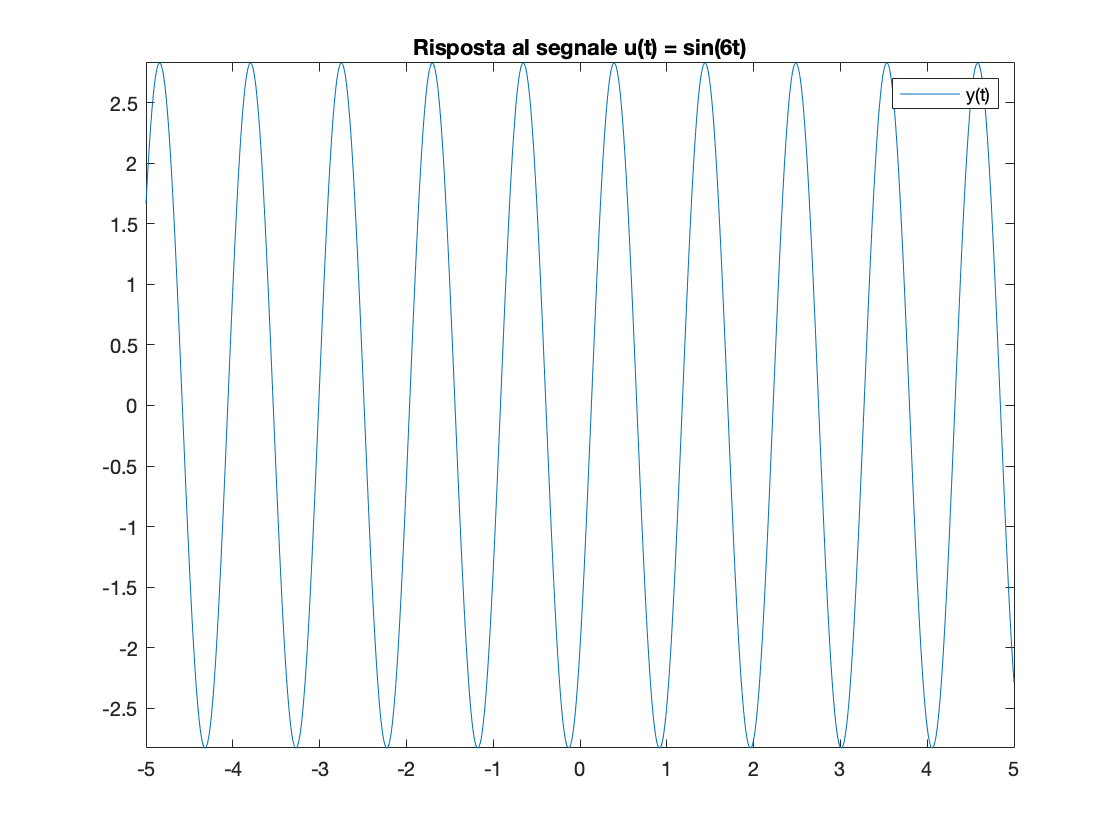

figure(3), fplot(y), title('Risposta al segnale u(t) = sin(6t)'), legend('y(t)')

Volendo essere più precisi, possiamo applicare la sovrapposizione degli effetti e calcolare anche la risposta alla sinusoide di frequenza pari a 60:

y1 = y;
y2 = simplify(abs(subs(G,s,1i*60)) * sin(60*t + angle(subs(G,s,1i*60))));
y = y1 + y2

$$y = \sqrt{8}\,\sin\left(6\,t-\frac{\pi }{4}\right)-\frac{\sqrt{3434}\,\sin\left(60\,t+\mathrm{atan}\left(\frac{995}{49}\right)\right)}{578}$$

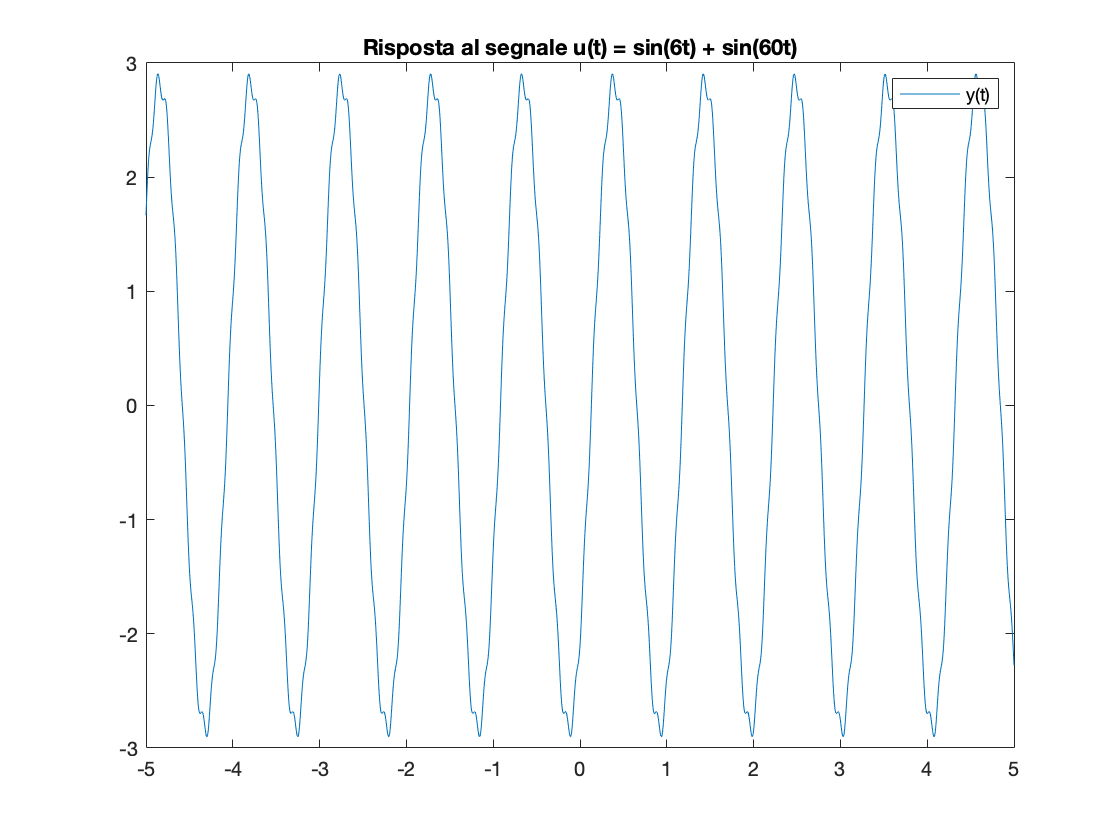

figure(4), fplot(y), title('Risposta al segnale u(t) = sin(6t) + sin(60t)'), legend('y(t)')

**Verifichiamo le risposte utilizzando lo state-space model di MATLAB**

Costruiamo il modello:

sys = tf(num,den)

sys =
 
     6 s + 36
  --------------
  s^2 + 3 s + 36
 
Continuous-time transfer function.



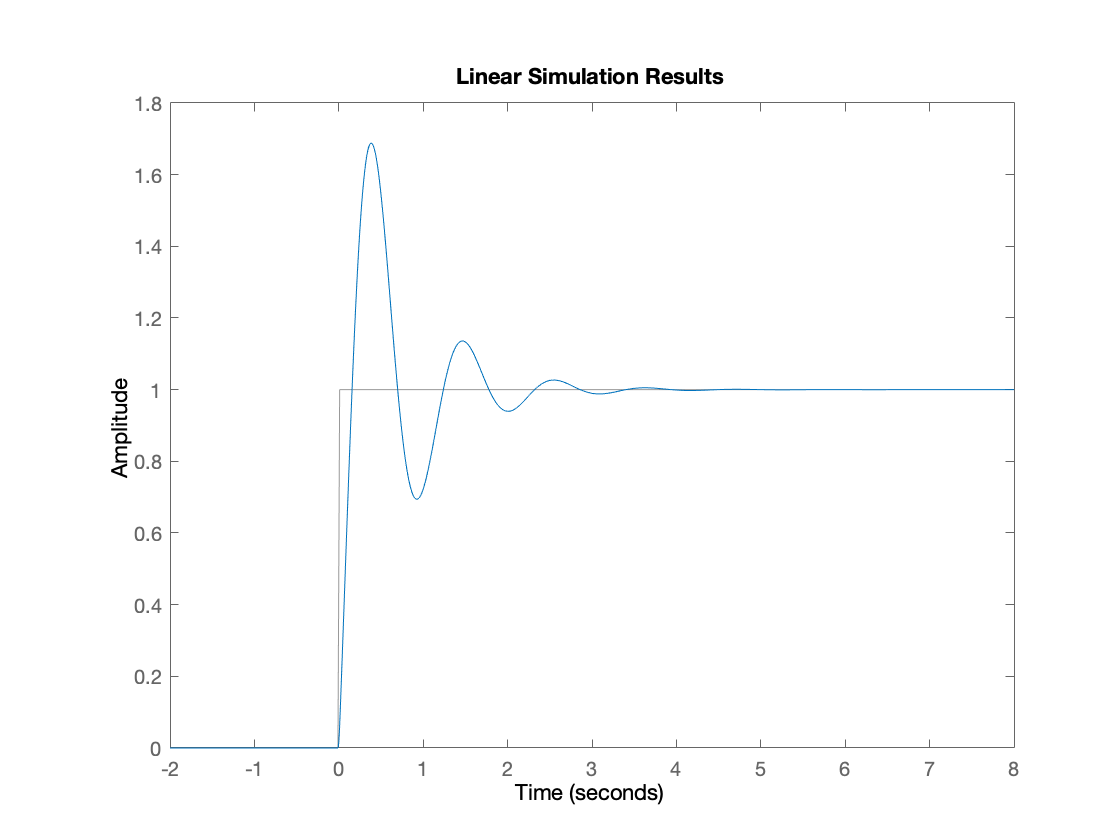

time = -2:0.01:8;
u = heaviside(time);
lsim(sys,u,time)

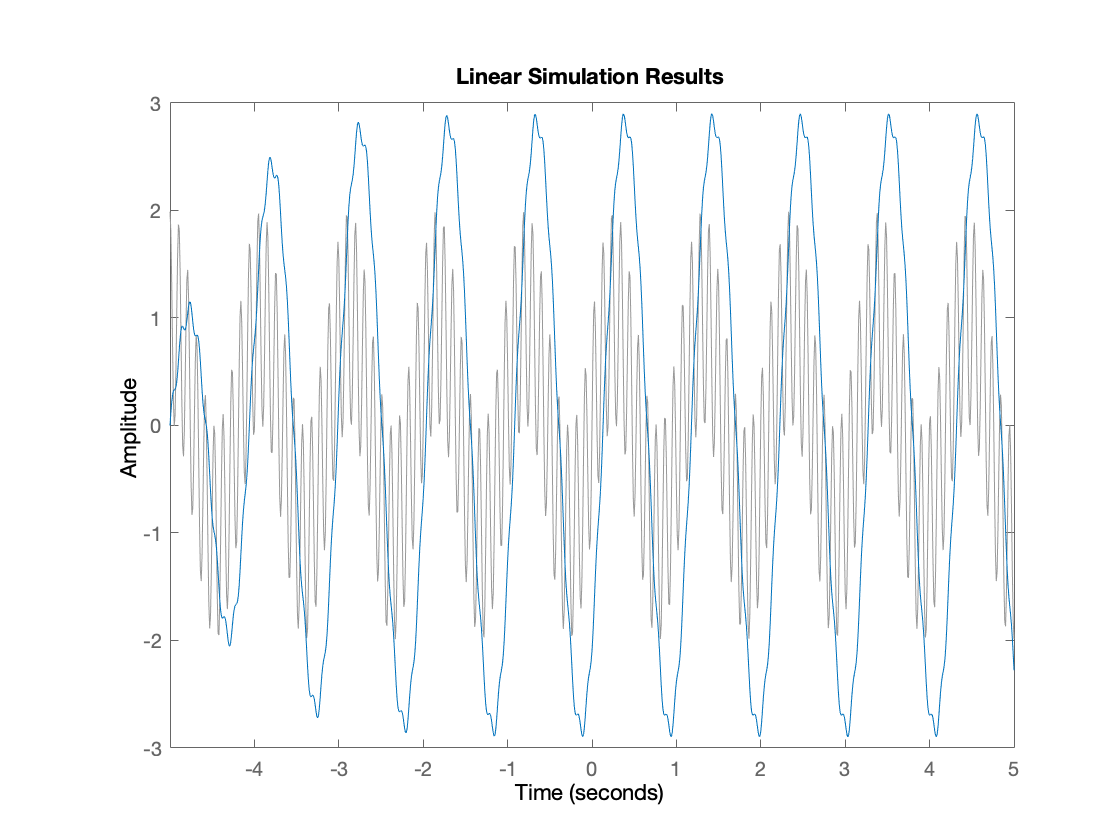

time = -5:0.01:5;
u = sin(6*time) + sin(60*time);
lsim(sys,u,time)

**Crediti:**

Esercizio di Marco Ariola. Svolgimento di Marco Ariola e Luigi Catello. Programma MATLAB di Luigi Catello.